% NxN Fourier Frequencies Matrix
N = 8

N = 8

n = [0:N-1]'

n =      0
     1
     2
     3
     4
     5
     6
     7


k = [0:N-1]

k =      0     1     2     3     4     5     6     7


V = exp((j*2*pi.*k.*n)/N)

V =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -0.7071 - 0.7071i  -0.0000 - 1.0000i   0.7071 - 0.7071i
   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i   1.0000 - 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i
   1.0000 + 0.0000i  -0.7071 + 0.7071i  -0.0000 - 1.0000i   0.7071 + 0.7071i  -1.0000 + 0.0000i   0.7071 - 0.7071i   0.0000 + 1.0000i  -0.7071 - 0.7071i
   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i  -0.7071 - 0.7071i   0.0000 + 1.0000i   0.7071 - 0.7071i  -1.0000 + 0.0000i   0.7071 + 0.7071i  -0.0000 - 1.0000i  -0.7071 + 0.7071i
   1.0000 + 0.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i   0.0000 + 1.0000i  


%Installment 1
%signal s from given spectrum S s = (1/N)VS
s1 = (1/8)*V(:, 1);
s2 = (1/8)*V(:, 5);
s3 = (1/8)*V(:, 2);
s4 = (1/8)*(V(:, 2) + V(:, 8));

%linearity and superposition
s1_ = s1 + s4 + s2;
s2_ = s1 + 5*s4 + 2*s2;

%Installment 2
sgiven = [2*sqrt(2) - 1, 1, -2*sqrt(2) - 1, 5, -2*sqrt(2) - 1, 1, 2*sqrt(2) - 1, -3]'

sgiven =     1.8284
    1.0000
   -3.8284
    5.0000
   -3.8284
    1.0000
    1.8284
   -3.0000


%spectrum S from given signal s S = V's
S = V'*sgiven

S =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
  11.3137 -11.3137i
  -8.0000 - 0.0000i
  11.3137 +11.3137i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i


%Check equivalent expression in terms of real-valued sinusoids
schecked = 2*cos((3*pi/4)*n - pi/4) - cos(pi*n) + 2*cos((5*pi/4)*n + pi/4)

schecked =     1.8284
    1.0000
   -3.8284
    5.0000
   -3.8284
    1.0000
    1.8284
   -3.0000



%vector of coefficient weights from given V and s c = (1/N)V's
Vgiven = [1, 1, 1, 1; 1, j, -1, -j; 1, -1, 1, -1; 1 -j, -1, j]

Vgiven =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i
   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 + 0.0000i   0.0000 + 1.0000i


sgiven2 = [1 4 -2 5]'

sgiven2 =      1
     4
    -2
     5


c = (1/4)*(Vgiven'*sgiven2)

c =    2.0000 + 0.0000i
   0.7500 + 0.2500i
  -2.5000 + 0.0000i
   0.7500 - 0.2500i



disp("good up to here")

good up to here



% NxN Fourier Frequencies Matrix
N2 = 5

N2 = 5

n2 = [0:N2-1]'

n2 =      0
     1
     2
     3
     4


k2 = [0:N2-1]

k2 =      0     1     2     3     4


V2 = exp((j*2*pi.*k2.*n2)/N2)

V2 =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i
   1.0000 + 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i
   1.0000 + 0.0000i  -0.8090 - 0.5878i   0.3090 + 0.9511i   0.3090 - 0.9511i  -0.8090 + 0.5878i
   1.0000 + 0.0000i   0.3090 - 0.9511i  -0.8090 - 0.5878i  -0.8090 + 0.5878i   0.3090 + 0.9511i



%signal x (= s) from given DFT (= Spectrum (S)) s = (1/N)VS
DFTgiven = [4, 1 + j, 3 - j, 3 + j, 1 - j]' 

DFTgiven =    4.0000 + 0.0000i
   1.0000 - 1.0000i
   3.0000 + 1.0000i
   3.0000 - 1.0000i
   1.0000 + 1.0000i


%DFTgiven = [0, 1, 0, 0, 1]'
ifft(DFTgiven)

ans =     2.4000
    0.0981
    1.4628
    0.2317
   -0.1925


disp("here")

here


x = (1/N2).*(V2*DFTgiven)

x =    2.4000 + 0.0000i
   0.0981 + 0.0000i
   1.4628 - 0.0000i
   0.2317 + 0.0000i
  -0.1925 + 0.0000i


%s (= x) checked by linear combination of real valued sinusoids for a real-valued signal
%xchecked = (4/N2) + (2/5)*((sqrt(2)*cos((2*pi*n2/5) + pi/4)) + (sqrt(10)*cos((4*pi*n2/5) - .32175))) %(2*sqrt(2)/N2)*cos(2*pi*n2/5 + pi/4) + (2*sqrt(10)/N2)*cos(4*pi*n2/5 - .3217)
xchecked = (DFTgiven(1)/N2) + (2/5) * (( abs(DFTgiven(2)) * cos((2*pi*n2/5) + angle(DFTgiven(2)))) + ( abs(DFTgiven(3))*cos((4*pi*n2/5) + angle(DFTgiven(3))) ))

xchecked =     2.4000
    0.0981
    1.4628
    0.2317
   -0.1925



%Nyquist Lab code

%sample and save data from the audio file
[data2, fs2] = audioread('04 - Song.m4a');
data2_channel1 = data2(:,1); %save the first column of the data, 
data2_channel1_excerpt = data2_channel1(30000:30200); %save an excerpt of the data
fft_of_data2_channel1_excerpt = fft(data2_channel1_excerpt);

%plot x-axis
n2 = 1:length(data2_channel1_excerpt); %x-axis Samples. Points n of x[n]
freq = n2*fs2/length(data2_channel1_excerpt);

Ts2 = 1/fs2

Ts2 = 2.0833e-05

fmax = 1/(2*Ts2) %the maximum frequnecy that is resolved by the FFT when sampled at fs2

fmax = 24000

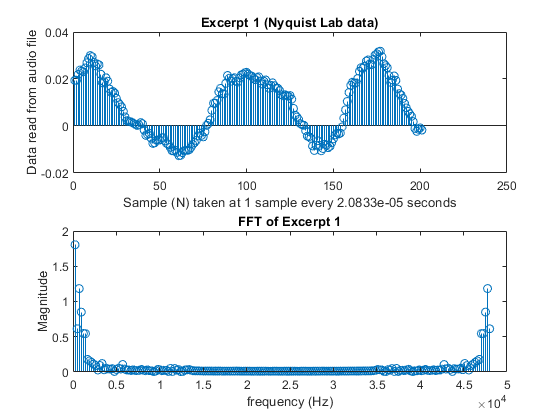

f = linspace(-fmax, fmax, 201); %the range of frequencies the FFT may have spaced by N samples the FFT has

%plot data versus time
figure(1)
subplot(2,1,1), stem(n2, data2_channel1_excerpt)
title("Excerpt 1 (Nyquist Lab data)");
xlabel("Sample (N) taken at 1 sample every 2.0833e-05 seconds"); %Sample (N) taken at 1 sample every 2.0833e-05 seconds
ylabel("Data read from audio file"); %Data read from audio file

%plot fft magnitude vs frequency
subplot(2,1,2), stem(freq, abs(fft_of_data2_channel1_excerpt))
title("FFT of Excerpt 1");
xlabel("frequency (Hz)");
ylabel("Magnitude");

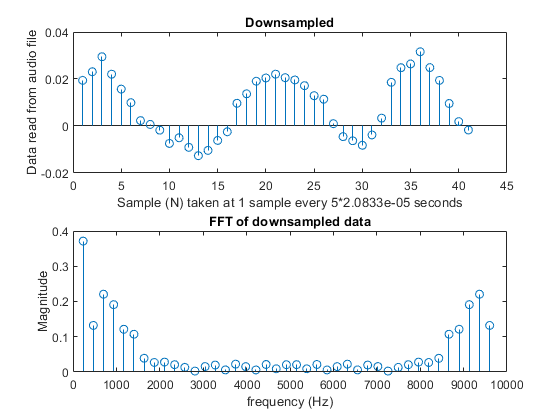


%DOWNSAMPLING BELOW
%downsample the data keeping every Nth point, like as if you sampled the
%data with a sampling period that is N times bigger

downsamplesize = 5;
downsampled_data2 = downsample(data2_channel1_excerpt, downsamplesize);
%downsampled_data2 = downsample(data2_channel1, downsamplesize); %downsample
%soundsc(downsampled_data2, fs2/downsamplesize)
fft_of_downsampled_data2 = fft(downsampled_data2);

%plot the discrete-time sinusoid data of the function versus time
n3 = 1:length(downsampled_data2); %x-axis Samples. Points n of x[n]
f2 = linspace(-fmax, fmax, numel(downsampled_data2)); %the range of frequencies the FFT may have spaced by N samples the FFT has
freq2 = n3*(fs2/downsamplesize)/length(downsampled_data2);

%plot data versus time
figure(2)
subplot(2,1,1), stem(n3, downsampled_data2)
title("Downsampled");
xlabel("Sample (N) taken at 1 sample every 5*2.0833e-05 seconds");
ylabel("Data read from audio file");

%plot fft magnitude vs frequency
subplot(2,1,2), stem(freq2, abs(fft_of_downsampled_data2))
title("FFT of downsampled data");
xlabel("frequency (Hz)");
ylabel("Magnitude");